# How does Absorption and Scattering change with Altitude?

# Where are most photons absorbed? 

# Where are most photons scattered?

## What are Weighting Functions?

#### The weighting function is a measure of the probability of absorption or emission occuring. It is not really a PDF, since it doesn't integrate to 1, but effectively it tells use the location in altitude where most of the absorption and emission occur. The weighting functon arrises from a variable transformation in the equation of radiative transfer. Lets walk through it. For a purely absorbing medium, our transfer equation is:


$$\frac{dI_{\lambda}}{d\tau_\lambda} = -I_\lambda + B_\lambda(T)$$


#### Which says the change in intensity over some slab of air with optical thickness $\tau_\lambda$ is equal to the intensity on the other side of the slab, plus the contribution due to thermal emission along this slab. 

## Coordinate Systems are important when using this equation!! 

#### We define the geometric coordinate system to vary from 0 at the surface to infinity above the atmosphere. $\tau_\lambda$ is defined as 0 at the observer, and increasing as the observer looks through more atmosphere. So $\tau_\lambda$ is defined to be 0 above the atmosphere and so number $\tau_\lambda^{*}$ at the surface. Therefore, if $\tau_\lambda$ is our coordinate system, then we want to know $I_\lambda(0)$ which depends on the intensity on the otehr side of the slab, $I_\lambda(\tau_\lambda^{*})$. The solution to our equation of radiative transfer is:


$$I_\lambda(0) = I_\lambda(\tau_\lambda^{*}) \exp(-\tau_\lambda) + \int_{0}^{\tau_\lambda^{*}} B(\tau_\lambda) \exp(-\tau_\lambda) \;d\tau_\lambda$$


#### If we wish to change coordinates from $\tau_\lambda$ to $z$, we take the derivative of the optical depth:


$$\frac{d\tau_\lambda}{dz} = \frac{d}{dz} \int_{0}^{z^{*}} \sigma^e_\lambda(z) N_c(z)\; dz =  \sigma^e_\lambda(z) N_c(z)$$


#### Therefore we can make the substitution:


$$d\tau_\lambda =  \sigma^e_\lambda(z) N_c(z)\;dz$$


#### If we plug this into our solution for the equation of radiative transfer, we get the following result:


$$I_\lambda(0) = I_\lambda(\tau_\lambda^{*}) \exp(-\tau_\lambda) + \int_{0}^{\tau_\lambda^{*}} B(\tau_\lambda) \exp(-\tau_\lambda) \; \sigma^e_\lambda(z) N_c(z)\;dz$$


#### Or, this expression is often written as:


$$I_\lambda(0) = I_\lambda(\tau_\lambda^{*}) \exp(-\tau_\lambda) + \int_{0}^{\tau_\lambda^{*}} B(\tau_\lambda) \exp(-\tau_\lambda) \; \frac{d\tau_\lambda}{dz} \;dz$$


#### The weighting function is this value of the optical depth changing with altitude, along with the transmisison:


$$W_\lambda(z) = \exp(-\tau_\lambda) \; \frac{d\tau_\lambda}{dz} = \exp(-\tau_\lambda) \; \sigma^e_\lambda(z) N_c(z)$$


####     Using the ideal gas law, we can convert number concentration to pressure and temperature. Since $N_c = \frac{N}{V} = \frac{p N_a}{R T}$ we can define the weighting function as:


$$W_\lambda(z) = \exp(-\tau_\lambda) \; \left(\frac{\sigma^e_\lambda(z) P(z)}{T(z)}\right) \left(\frac{N_a}{R}\right) =  \exp(-\tau_\lambda) \; \left(\frac{\sigma^e_\lambda(z) \rho(z)}{M(z)} \right) N_a$$


#### Where we can specify the absorption or emisison at some height in the atmosphere by its pressure and temperature, or by the density. $M$ is the molar mass of air at that altitude. $N_a$ is avogadro's number, and $R$ is the universal gas constant. 

## So How do we compute the weighting function?

## A Simple Adiabatic Troposphere Model

clear variables
scriptPlotting_wht

% Lets inroduce some constants!
con = physical_constants();

g0 = con.g0;                        % m/s^2 - gravity vector
R = con.R;                          % Pa*m^3/(K*mol)
Na = con.N_A;                       % molec/mole - avogadro's number
M_air = con.M_air;                  % kg/mol - molar mass of air
L_a = g0/con.cp_air;                % K/m - adiabatic lapse rate


% -----------------------------------------------------------------
% Define a linear temperature profile
T0 = 300;                           % K - surface temperature

% ----- Linear Temperature Profile ---------
%T = @(z) T0 - L_a*z;               % K - temperature profile

% ---- Constant Temperature Profile ----------
T = @(z) T0*(z.^0);                 % K - constant temperature profile

% ------------------------------------------------------------------

% Lets set up an altitude vector
z = 0:100:1e4;                      % meters - altitude vector


## The temperature profile is enough to determine the pressure profile

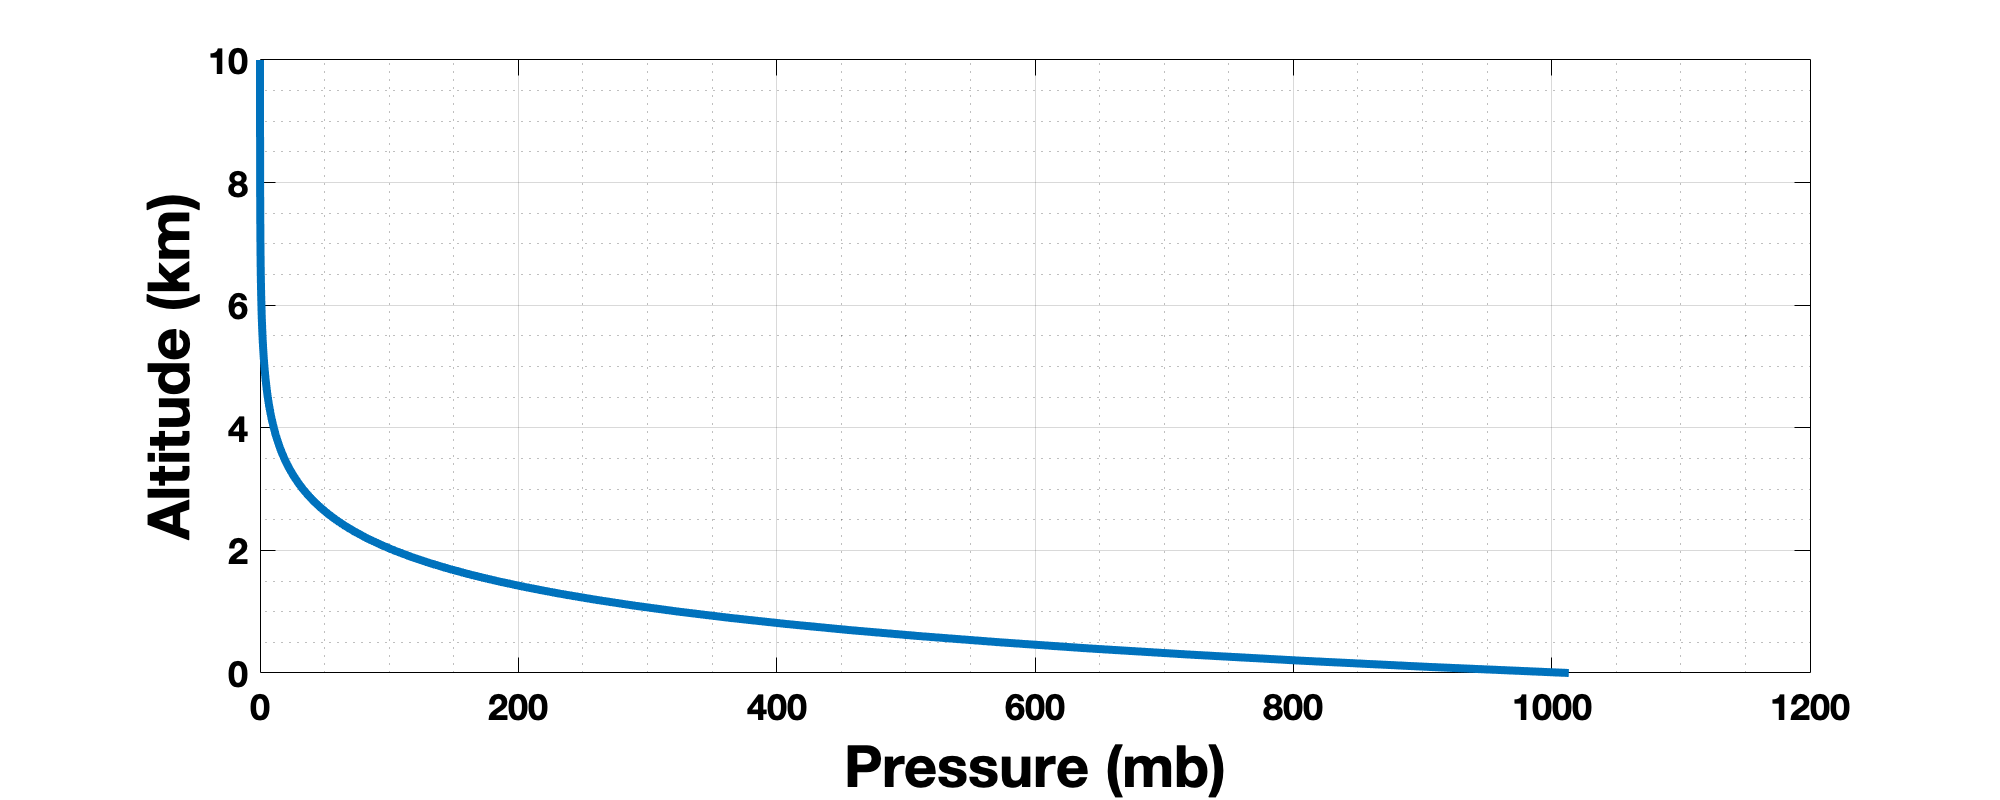


% Define the pressure profile
P0 = con.atm;                                           % Pa - surface pressure
P = zeros(1,length(z));                     % pressure vector
for ii = 1:length(z)
    
    dz = linspace(z(1),z(ii),100);
    P(ii) = P0*exp(-g0/(R/M_air) * trapz(dz,1./T(dz)));         % Pa - pressure profile

end

% -----------------------
% How do I fix the sign??
% -----------------------

%P = P0*exp(g0/((R/M_air)*L_a) * log(T(z)./T0));





% Plot the temperature and pressure profile on the same plot

% t = tiledlayout(1,1);
% ax1 = axes(t);
% plot(ax1,P./100, z./1e3,'-k')
% hold on
% ax1.XColor = 'k';
% ax1.YColor = 'k';
% %ax1.XLim = [1e-2 1e3];
% ax1.XLabel.String = 'Pressure (mb)';
% ax1.YLabel.String = 'Height (km)';
% ax1.FontSize = 14;
% grid on; grid minor
% %legend('Pressure','Location','best')
% 
% color2 = [0.8500 0.3250 0.0980]	;
% ax2 = axes(t);
% plot(ax2,T,z./1e3,'--','Color',color2)
% ax2.FontSize = 14;
% ax2.YAxis.TickLength = [0 0];
% ax2.YTickLabel = [];
% ax2.YLim = [0 100];
% ax2.XColor = color2;
% ax2.XAxisLocation = 'top';
% ax2.Color = 'none';
% ax2.XLabel.String = 'Temperature (K)';

% Lets plot the pressure and temperature separately

% plot pressure
f = figure;
plot(P./100, z./1e3); 
ylabel('Altitude (km)'); xlabel('Pressure (mb)')
grid on; grid minor;
hold on;
set(f, 'Position', [0 0 1000 400])

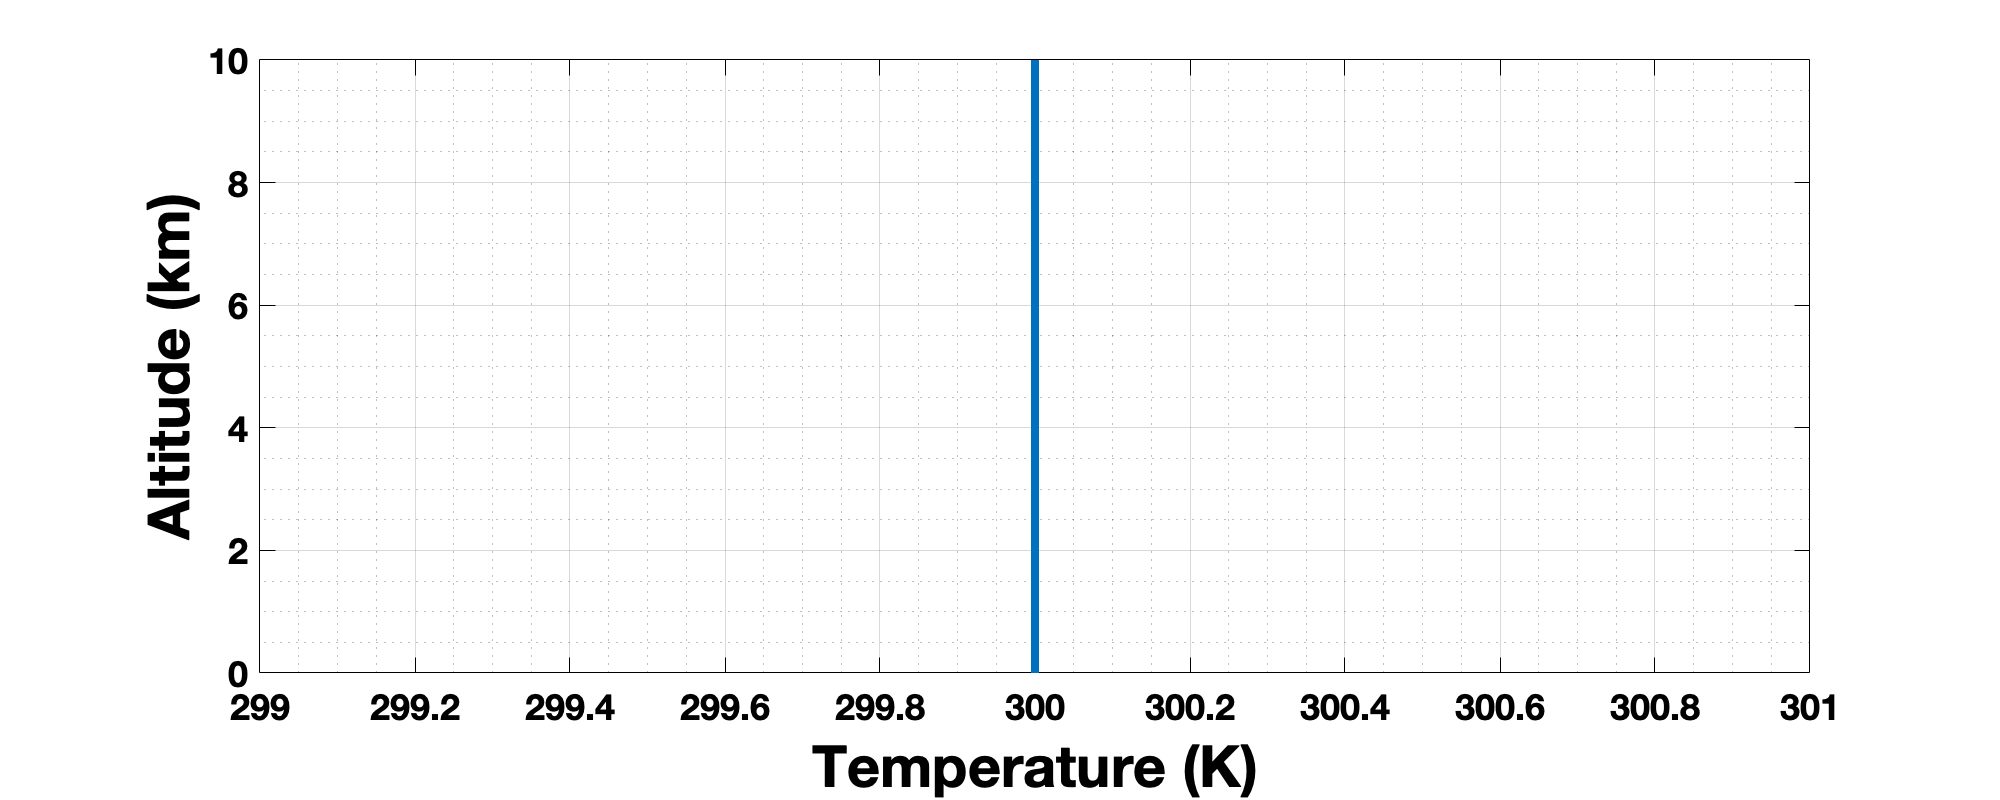

% Plot temperature
f = figure;
plot(T(z), z./1e3); 
ylabel('Altitude (km)'); xlabel('Temperature (K)')
grid on; grid minor;
hold on;
set(f, 'Position', [0 0 1000 400])

## How does the absorption change with altitude?

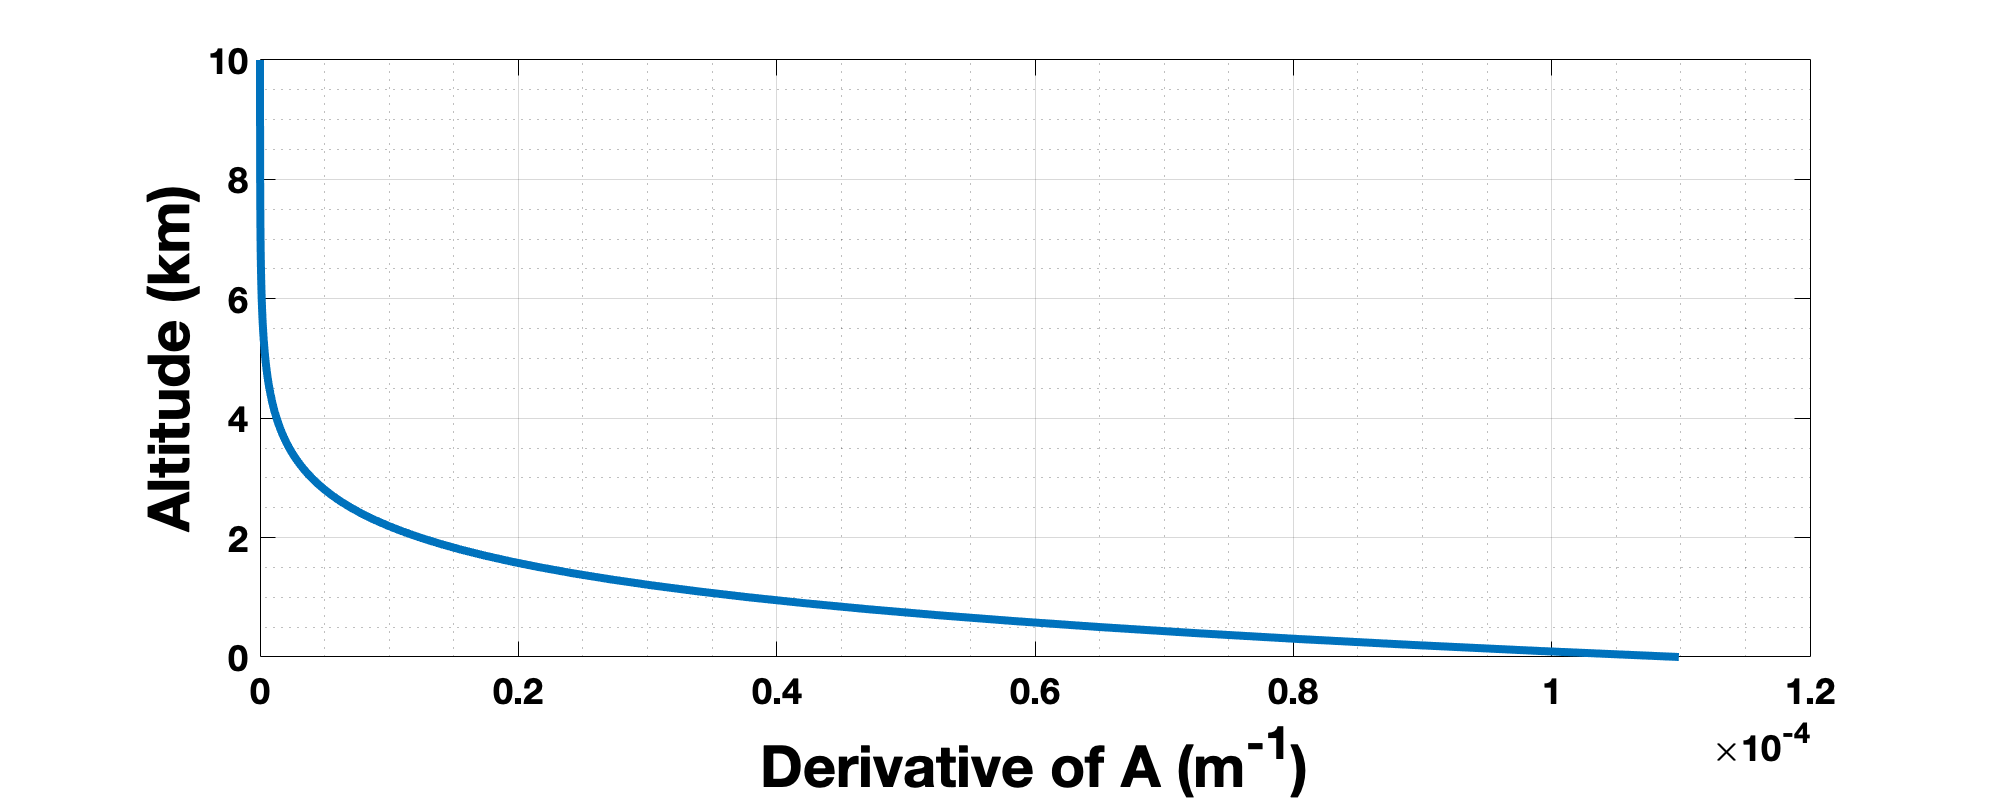

% Now that we have the pressure profile, we can compute the weighting
% functions

% define the absorption cross section
avg_absorption_cross_section = 5e-26 /10^4;               % m^2 - absorption cross section of water

% define the zenith angle of the source
theta = 0;                                          % deg - zenith angle
theta_rad = theta * (pi/180);                       % rad - zenith angle

% Remember, we are a space craft looking down on Earth. So we want our
% coordniate system to start at a z=inf (tau=0) and end at some z=z' (tau =
% tau')

z_fromSpace = fliplr(z);
T_fromSpace = T(z_fromSpace);
P_fromSpace = fliplr(P);

tau = zeros(1,length(z));
dA_dz = zeros(1,length(z));

for ii = 2:length(z_fromSpace)
    
    % we integrate from inf to each point along z
    % lets create a new z interval for integration
    
    
    % We need to compute the optical depth
    
    tau(ii) = -trapz(z_fromSpace(1:ii), Na*avg_absorption_cross_section/R * P_fromSpace(1:ii)./T_fromSpace(1:ii));           % optical depth
    
    transmission = exp(-tau(ii)*sec(theta_rad));                        % unitless - the transmission
    
    % Compute the derivative of absorption
    
    dA_dz(ii) = transmission * (Na*sec(theta_rad)/R) * avg_absorption_cross_section * P_fromSpace(ii)./T_fromSpace(ii);       %1/m - 
       

end


% Plot The derivative of absorption

f = figure;
plot(dA_dz, z_fromSpace./1e3); 
ylabel('Altitude (km)'); xlabel('Derivative of A (m^{-1})')
grid on; grid minor;
hold on;
set(f, 'Position', [0 0 1000 400])

## Lets Plot dA/dz with different values of the absorption coefficient

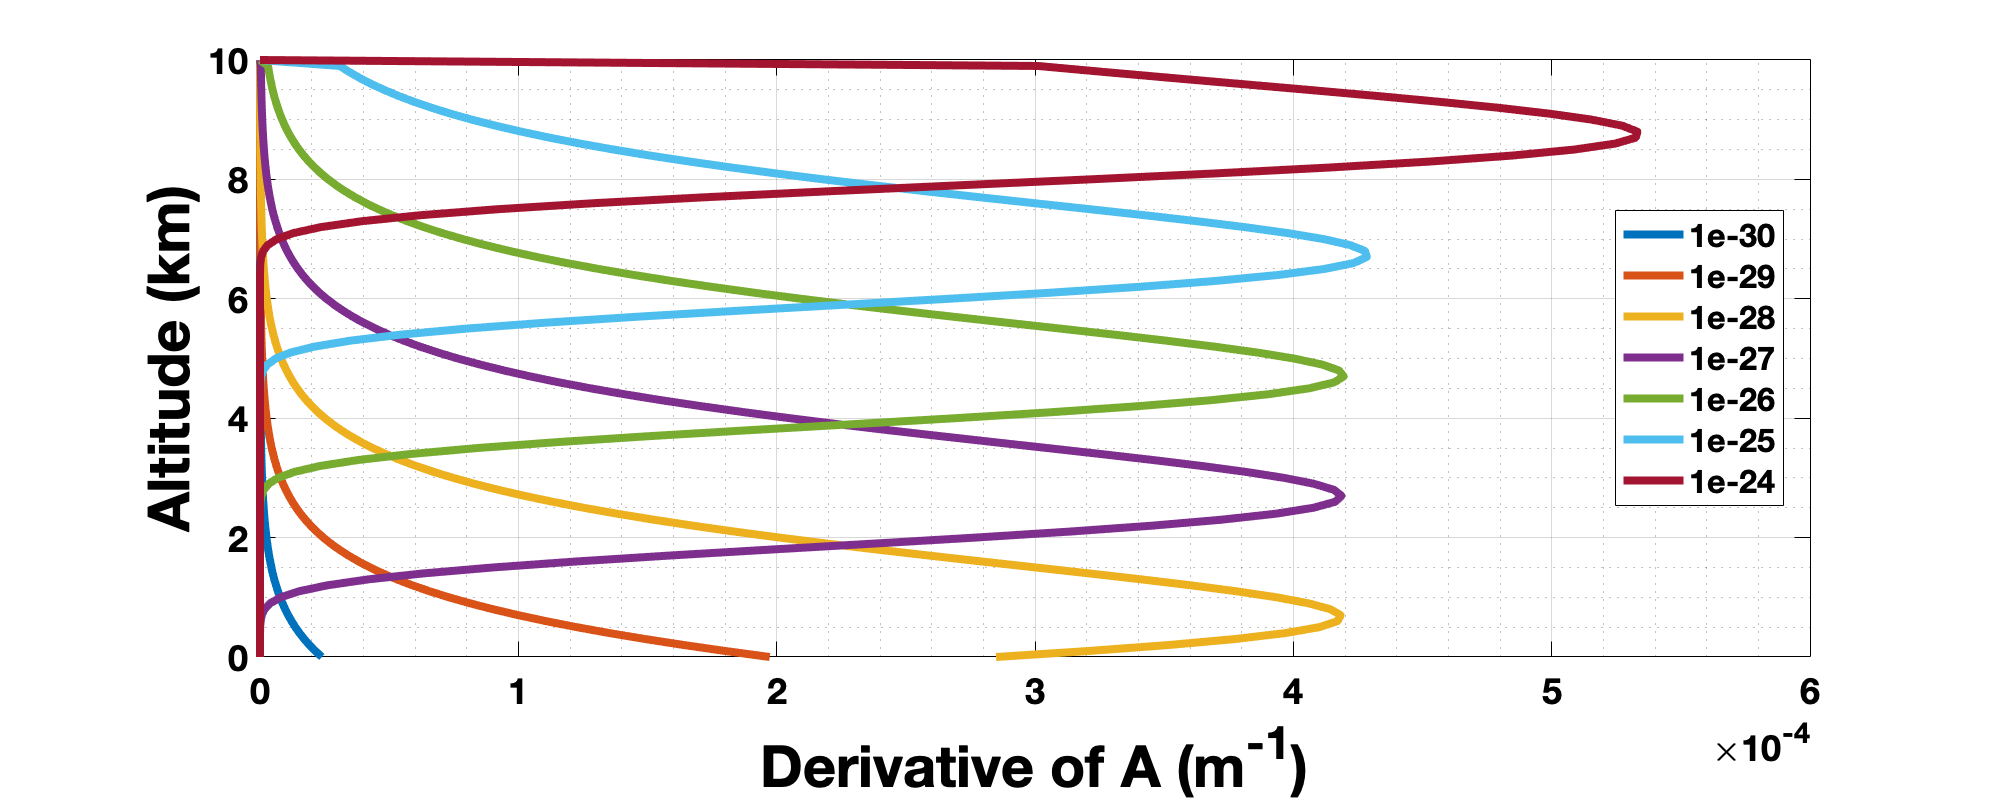


% define the absorption cross section
avg_absorption_cross_section = logspace(-26,-20,7)./10^4;               % m^2 - absorption cross section of water


tau = zeros(length(avg_absorption_cross_section),length(z));
dA_dz = zeros(length(avg_absorption_cross_section),length(z));

% initialize the figure!

f = figure;

for jj = 1:length(avg_absorption_cross_section)
    for ii = 2:length(z_fromSpace)
    
        % we integrate from inf to each point along z
        % lets create a new z interval for integration
        
        
        % We need to compute the optical depth
        
        tau(jj,ii) = -trapz(z_fromSpace(1:ii), Na*avg_absorption_cross_section(jj)/R * P_fromSpace(1:ii)./T_fromSpace(1:ii));           % optical depth
        
        transmission = exp(-tau(jj,ii)*sec(theta_rad));                        % unitless - the transmission
        
        % Compute the derivative of absorption
        
        dA_dz(jj,ii) = transmission * (Na*sec(theta_rad)/R) * avg_absorption_cross_section(jj) * P_fromSpace(ii)./T_fromSpace(ii);       %1/m - 
        
    end
    
    plot(dA_dz(jj,:), z_fromSpace./1e3); 
    hold on;
    

end


% Plot The derivative of absorption

ylabel('Altitude (km)'); xlabel('Derivative of A (m^{-1})')
grid on; grid minor;
legend(string(avg_absorption_cross_section),'Location',"best")
set(f, 'Position', [0 0 1000 400])